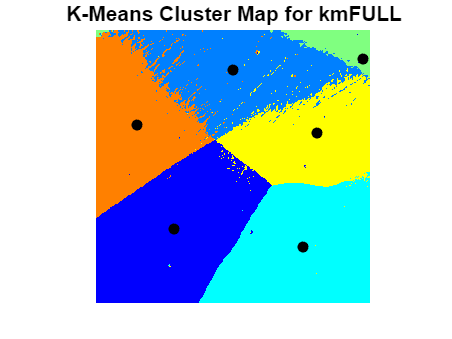

plotKMeansClusterMap('KmediodFULLcluster.mat', 'kmFULL');

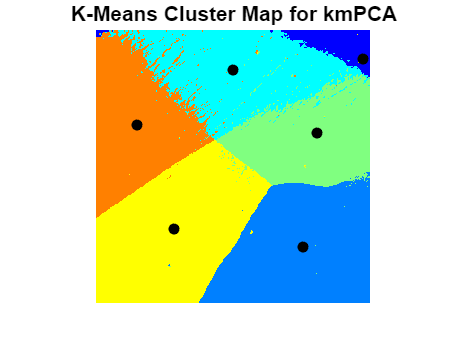

plotKMeansClusterMap('KmediodPCAcluster.mat', 'kmPCA');

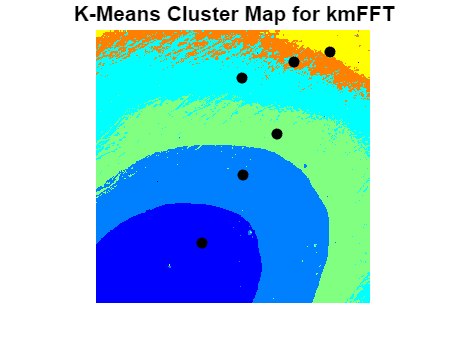

plotKMeansClusterMap('KmediodFFTcluster.mat', 'kmFFT');

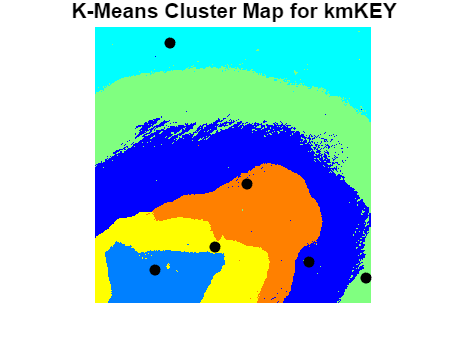

plotKMeansClusterMap('KmediodKEYCluster.mat', 'kmKEY');

function plotKMeansClusterMap(matFile, dataFieldName)
    % Load the dataset
    data = load(matFile);

    % Extract centroids assuming centroids are stored in a 2D format
    centroids = data.(dataFieldName).C; % Check the structure of data file for actual variable names
    if size(centroids, 2) < 2
        error('Centroids must have at least two dimensions.');
    end
    centroidIdx = data.(dataFieldName).midx;
    % Clusters
    Cls = data.(dataFieldName).idx;
    cmap = jet(size(centroids, 1));
    Colors = cmap(Cls, :);
    % Build XY index
    [X, Y] = meshgrid(1:304, 1:304);
    X = reshape(X, [], 1);
    Y = reshape(Y, [], 1);
    
    % Create colored map
    figure;
    scatter(X, Y, 1, Colors, ".")
    axis image off; % Hide axis for a cleaner look
    title(sprintf('K-Means Cluster Map for %s', dataFieldName));
    hold on
    scatter(X(centroidIdx), Y(centroidIdx), 30, 'black', "filled", "o")
    hold off
    % Save the image to a file
    saveas(gcf, [dataFieldName, '_ClusterMap.png']);
end
